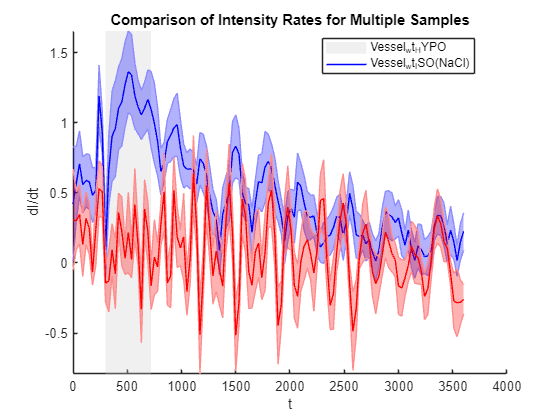

clear
DataTable = readtable('ProcessedVesselData.xlsx', 'Sheet', 'Intensity_Rate', 'VariableNamingRule', 'preserve');
ColNames = DataTable.Properties.VariableNames;

% Extract the time data as an array
Time = DataTable.Time;

% Define the list of SampleIDs you want to analyze
SampleIDs = {'Vessel_wt_HYPO', 'Vessel_wt_ISO(NaCl)'};  % Add as many SampleIDs as needed

% Define colors for each sample (can add more if needed)
colors = {'-b', '-r', '-g', '-m', '-c', '-y', '-k'};  % Cycle through these if there are more SampleIDs

% Define the time intervals to highlight, e.g., [start, end]
highlightIntervals = [300, 720];  % Modify or add intervals as needed

% Check if there are enough colors for the number of SampleIDs
if length(SampleIDs) > length(colors)
    warning('Not enough colors defined for the number of SampleIDs; some colors will repeat.');
end

% Create a figure for plotting
figure;
hold on;

% Set initial y-axis limits for shaded regions (will be updated after first plot)
yLimits = [0, 1];  % Adjust these initial values if needed

% Loop over each SampleID in the list to calculate y-axis limits dynamically
for i = 1:length(SampleIDs)
    SampleID = SampleIDs{i};
    
    % Find the columns corresponding to the current SampleID
    indSample = find(contains(ColNames, SampleID));
    
    % Check if data exists for the current SampleID
    if isempty(indSample)
        warning(['No data found for SampleID: ', SampleID]);
        continue;
    end
    
    % Calculate mean, standard deviation, and standard error across columns for this sample
    meanValues = mean(table2array(DataTable(:, indSample)), 2, 'omitnan');
    stdValues = std(table2array(DataTable(:, indSample)), 0, 2, 'omitnan');
    stderrValues = stdValues / sqrt(numel(indSample));
    
    % Update y-axis limits based on current sample data
    yLimits = [min([yLimits(1); meanValues - stderrValues]), max([yLimits(2); meanValues + stderrValues])];
end

% Plot the highlighted regions first
for k = 1:size(highlightIntervals, 1)
    x = [highlightIntervals(k, 1), highlightIntervals(k, 2), highlightIntervals(k, 2), highlightIntervals(k, 1)];
    y = [yLimits(1), yLimits(1), yLimits(2), yLimits(2)];
    fill(x, y, [0.8, 0.8, 0.8], 'FaceAlpha', 0.3, 'EdgeColor', 'none'); % Use RGB for gray
end

% Loop over each SampleID in the list again to plot data
for i = 1:length(SampleIDs)
    SampleID = SampleIDs{i};
    
    % Find the columns corresponding to the current SampleID
    indSample = find(contains(ColNames, SampleID));
    
    % Check if data exists for the current SampleID
    if isempty(indSample)
        continue;
    end
    
    % Calculate mean, standard deviation, and standard error across columns for this sample
    meanValues = mean(table2array(DataTable(:, indSample)), 2, 'omitnan');
    stdValues = std(table2array(DataTable(:, indSample)), 0, 2, 'omitnan');
    stderrValues = stdValues / sqrt(numel(indSample));
    
    % Choose a color for each plot (cycle through colors if necessary)
    color = colors{mod(i-1, length(colors)) + 1};
    
    % Plot using shadedErrorBar
    shadedErrorBar(Time, meanValues, stderrValues, 'lineProps', color, 'patchSaturation', 0.3);
end

% Labels and title
xlabel('t');
ylabel('dI/dt');
title('Comparison of Intensity Rates for Multiple Samples');
legend(SampleIDs, 'Location', 'Best');

% Set y-axis limits after plotting
ylim(yLimits);
hold off;

drawnow;  % Ensure figure updates immediately
